Author: Warren Chan

Date: 2022-03-20

Source for step_load_forces: code written by Gabriel Chen

This livescript is to demonstrate obtaining the averages from the synchornized data

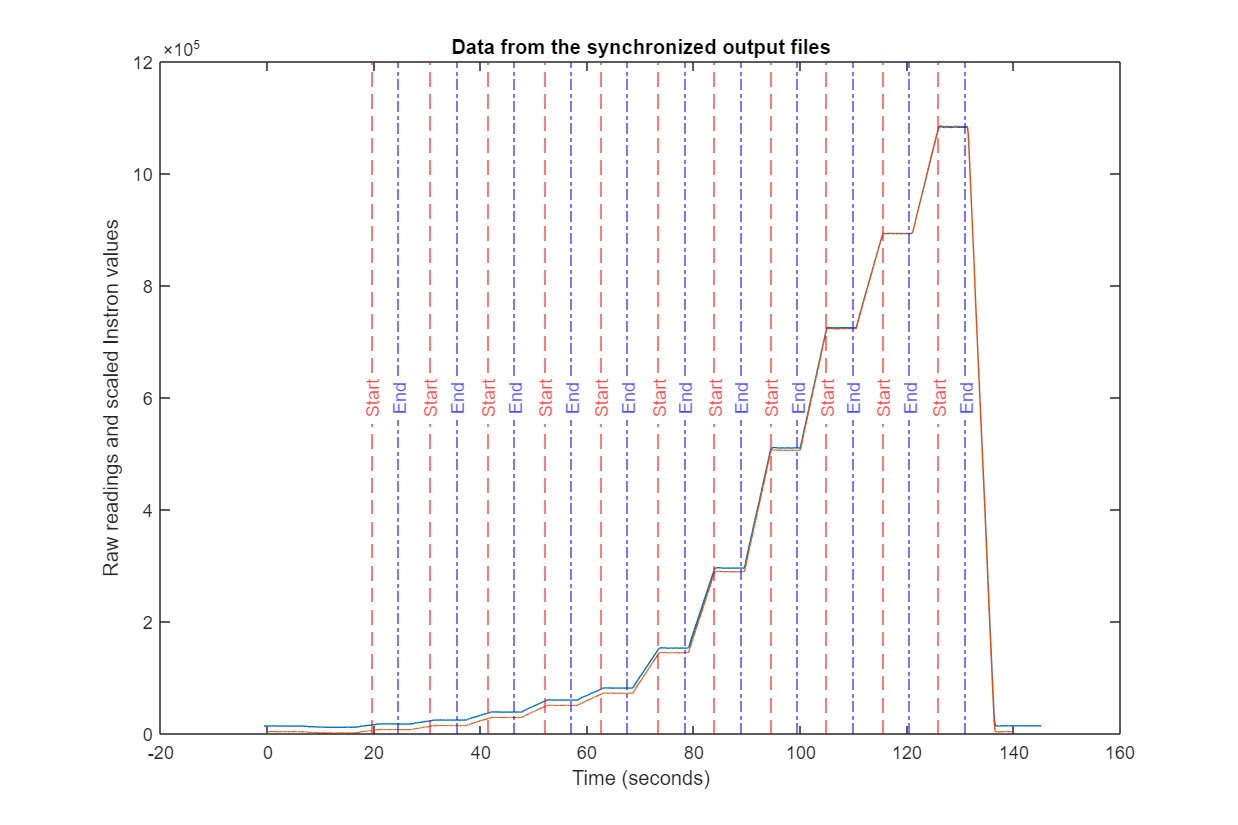

clear;

load_cell_number = 3;
test_number = 2;

%read the data from the synchronized output files
sync_MCU_filename = "SyncOutputFiles\MCUSteppedLoading_LC"+load_cell_number+"_T"+test_number+".csv";
sync_Instron_filename = "SyncOutputFiles\InstronSteppedLoading_LC"+load_cell_number+"_T"+test_number+".csv";

MCU_data = readtable(sync_MCU_filename);
Instron_data = readtable(sync_Instron_filename);

%get the data into vectors
MCU_time = MCU_data{:,1};
MCU_load = MCU_data{:,2};
Instron_time = Instron_data{:,1};
Instron_load = Instron_data{:,2};

%scaling factor for visualization of the instron data
scaling_factor = (1000/1.3831);

%plot the information obtained just for visualization purposes:
plot(MCU_time, MCU_load);
hold on
plot(Instron_time, Instron_load.*scaling_factor);
title ("Data from the synchronized output files");
xlabel("Time (seconds)");
ylabel("Raw readings and scaled Instron values");

interval_duration = 5; %seconds

%defined in the protocol
%source: Gabriel Chen
step_loads_force = [10.00... 
                    20.00... 
                    40.00... 
                    70.00... 
                    100.00... 
                    200.00... 
                    400.00... 
                    700.00... 
                    1000.00... 
                    1236.00... 
                    1500.00].';

%find out the time ranges to be averaged:
force_tolerance = 2; % in N, subject to be changed

%finding the step start times:
step_start_times = zeros(11,1);
step_end_times= zeros(11,1);

for step_index = 1:length(step_loads_force) 
    for item = 1:length(Instron_load)
        if(Instron_load(item) > (step_loads_force(step_index) - force_tolerance))
            step_start_times(step_index) = Instron_time(item);
            step_end_times(step_index) = step_start_times(step_index) + interval_duration;

            xlstart = xline(step_start_times(step_index), '--r', "Start");
            xlstart.LabelVerticalAlignment = 'middle';
            xlstart.LabelHorizontalAlignment = 'center';
            xlend = xline(step_end_times(step_index), '-.b', "End");
            xlend.LabelVerticalAlignment = 'middle';
            xlend.LabelHorizontalAlignment = 'center';
            break;
        end
    end
end
set(gcf,'position',[10,10,900,600]);
hold off;

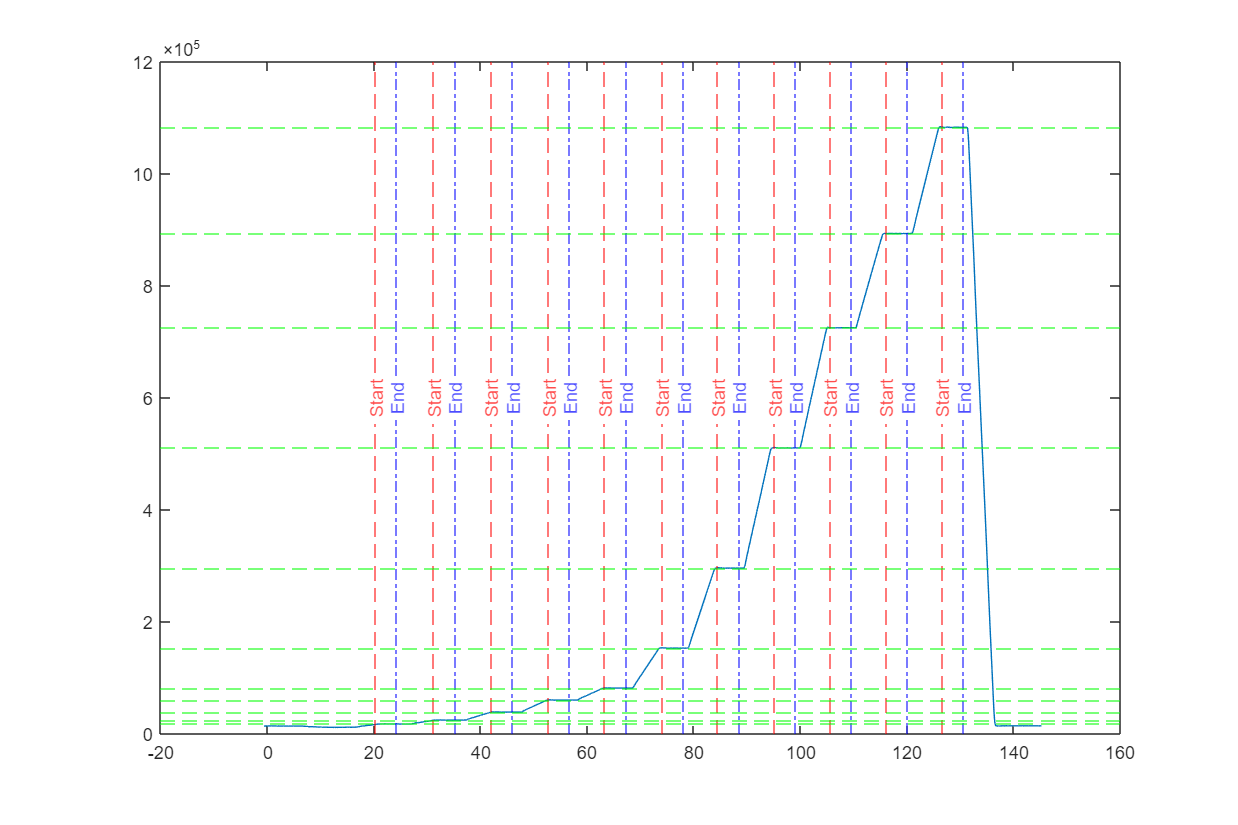


%time tolerance defined here
start_time_tolerance = 0.6; %seconds
end_time_tolerance = 0.4; %seconds

MCU_step_start_index = zeros(11,1);
MCU_step_end_index = zeros(11,1);

%now to average the values over in MCU;
for step_index = 1: length(step_loads_force)
    for item = 1: length(MCU_load)
        if (MCU_time(item) >= (step_start_times(step_index)+start_time_tolerance)) %notice the PLUS tolerance
            MCU_step_start_index(step_index) = item; %grab the index
            break;
        end
    end
end
for step_index = 1: length(step_loads_force)
    for item = 1: length(MCU_load)
        if (MCU_time(item) >= (step_end_times(step_index)-end_time_tolerance)) %notice the MINUS tolerance
            MCU_step_end_index(step_index) = item; %grab the index
            break;
        end
    end
end
plot(MCU_time, MCU_load);
hold on
for step_index= 1:length(step_loads_force)
    xlstart = xline(MCU_time(MCU_step_start_index(step_index)), '--r', "Start");
    xlstart.LabelVerticalAlignment = 'middle';
    xlstart.LabelHorizontalAlignment = 'center';
    xlend = xline(MCU_time(MCU_step_end_index(step_index)), '-.b', "End");
    xlend.LabelVerticalAlignment = 'middle';
    xlend.LabelHorizontalAlignment = 'center';
end


% visual check completed
% obtain averages:
MCU_raw_averages  = zeros(11,1);

for step_index = 1:length(step_loads_force)
    MCU_raw_averages(step_index) = mean(MCU_load(MCU_step_start_index(step_index):MCU_step_end_index(step_index),1));
    ylaverage = yline(MCU_raw_averages(step_index), '--g');
    set(gcf,'position',[10,10,900,600]);
end
hold off

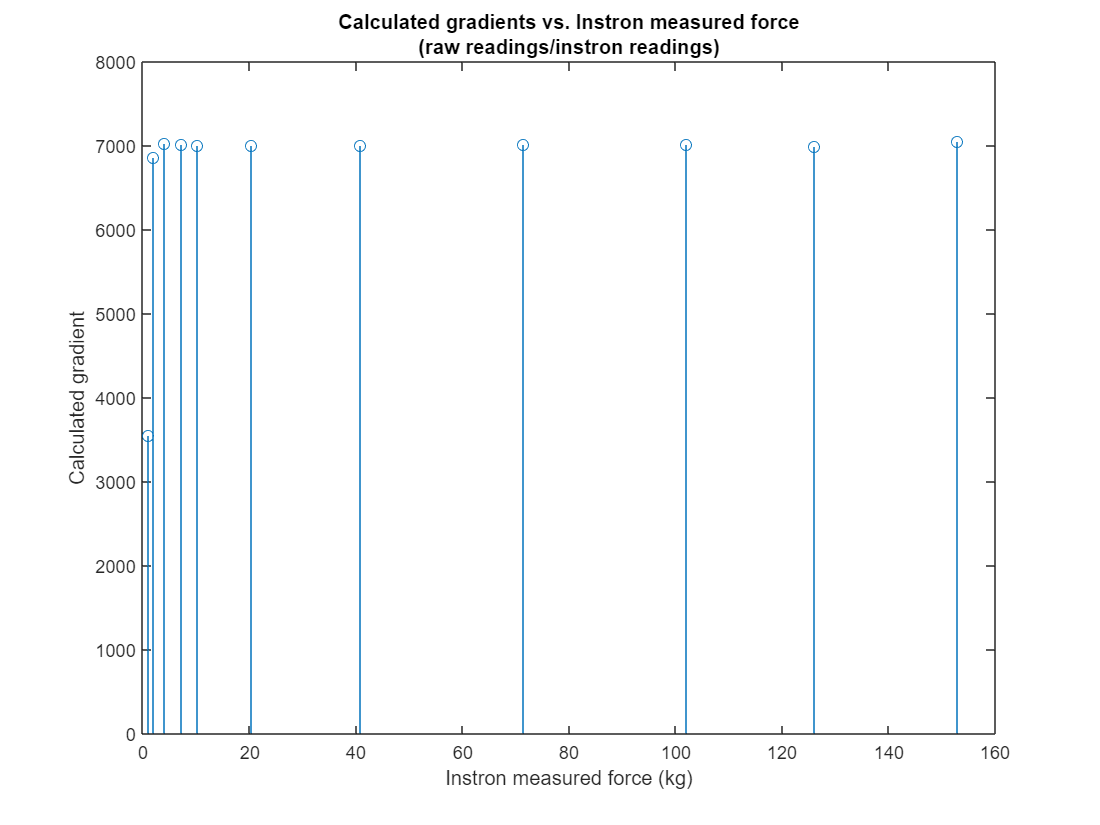

%plot the curve of the gradients:

%obtain the zero offset from the first 5 seconds of the MCU data:
zero_offset_start_index = 1; %start from the beginning

for item = 1:length(MCU_time)
    if(MCU_time(item) >= 5)
        zero_offset_end_index = item;
        break;
    end
end

zero_offset = mean(MCU_load(zero_offset_start_index:zero_offset_end_index, 1));

gradient_vector = zeros(11,1);

% One kilogram-force is equal to 9.80665 N\

onekilogram_to_N = 9.80665;
N_to_kg = 1/onekilogram_to_N;

for gradient_index = 1:length(gradient_vector)
    
    if (gradient_index == 1)
        gradient_vector(gradient_index) = (MCU_raw_averages(gradient_index)-zero_offset)/((step_loads_force(gradient_index)-0)*N_to_kg);
    else 
        gradient_vector(gradient_index) = (MCU_raw_averages(gradient_index)-MCU_raw_averages(gradient_index-1))/((step_loads_force(gradient_index)-step_loads_force(gradient_index-1))*N_to_kg);
    end
end

stem(step_loads_force.*N_to_kg, gradient_vector);
hold on
xlabel("Instron measured force (kg)");
ylabel("Calculated gradient");
titlestring = ["Calculated gradients vs. Instron measured force", "(raw readings/instron readings)"];
title(titlestring);
hold off